The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 08-Apr-2020




Location = 'Slovakia';


try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1);
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1);
    indD = find(contains(tableDeaths.CountryRegion,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));    
end

disp(tableRecovered(indR,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

      <missing>       "Slovakia"  



disp(tableConfirmed(indC,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

      <missing>       "Slovakia"  



disp(tableDeaths(indD,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

      <missing>       "Slovakia"  




indR = indR(1);
indD = indD(1);
indC = indC(1);

Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= round(0.025*max(Confirmed));
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end


Npop= 5.4e6; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.1; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     2.63819e+06                      8.39e+07
     1         18          788380      0.0986621       3.97e+07      
     2         27         81887.9       0.044643        8.5e+06      
     3         36           21840      0.0444166       4.59e+05      
     4         45           21840       0.167222       4.59e+05      
     5         54           19633      0.0418054       5.97e+04      
     6         63           16985      0.0836108        1.6e+05      
     7         72         13909.2       0.128137       4.97e+04      
     8         81         11468.4       0.167222       1.78e+05      
     9         90         11468.4       0.262235       1.78e+05      
    10         99         10252.2      0.0655589       6.68e+04      
    11        108         10065.3       0.131118       2.89e+05      
    12        117         8490.8

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(1)));
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

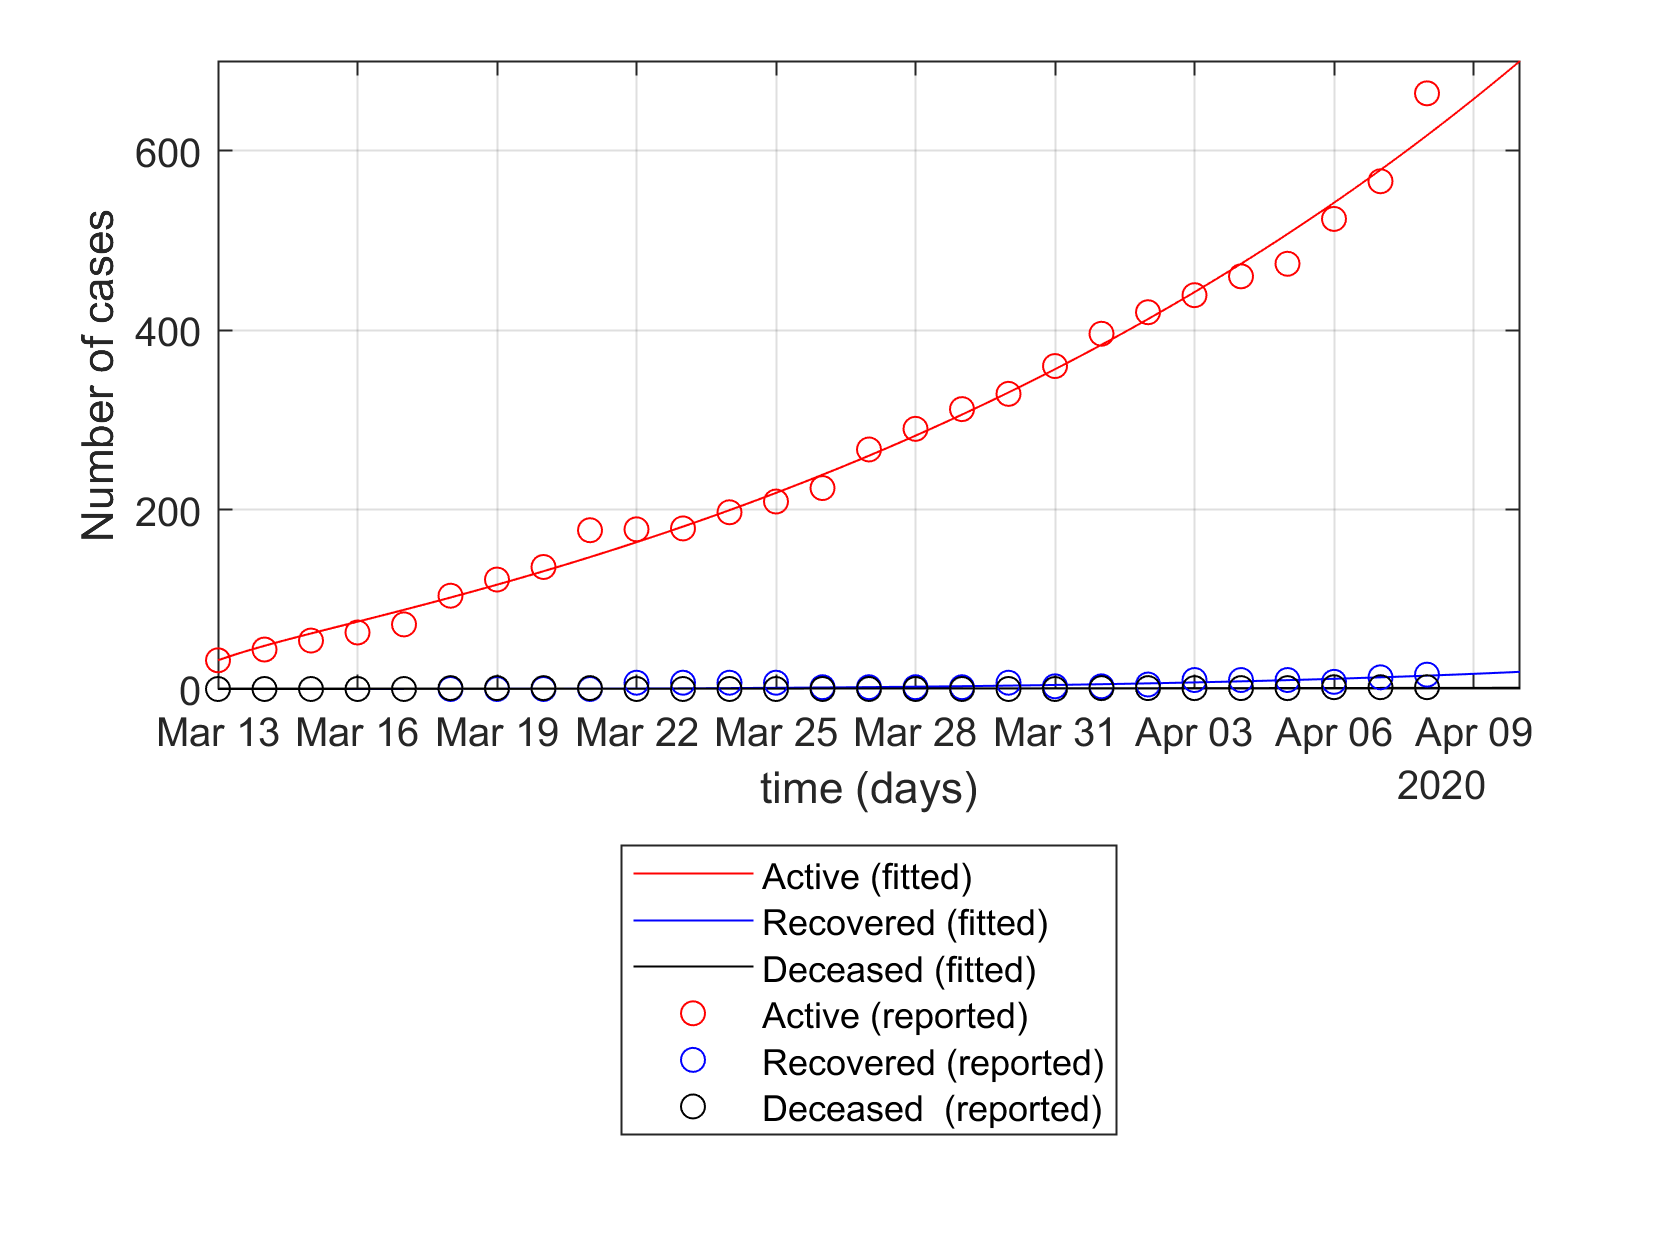

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Active (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
 set(gca,'yscale','lin')